clear; clc;

## Helicopter Model

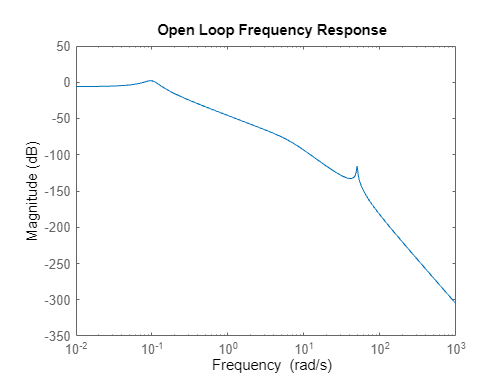

s = tf('s');

Om1 = 0.1; z1 = 0.2; % Phugoid
Om2 = 6.5; z2 = 0.7; % Short period
Om3 = 50; z3 = 0.01; % Flex mode

G1 = tf(Om1^2,[1 2*z1*Om1 Om1^2]);
G2 = tf(Om2^2,[1 2*z2*Om2 Om2^2]);
G3 = tf(Om3^2,[1 2*z3*Om3 Om3^2]);
G = 0.5*G1*G2*G3;

figure(1)
bodemag(G); title('Open Loop Frequency Response')

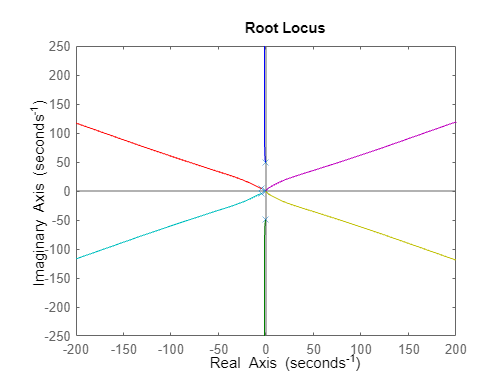

rlocus(G)

% print -depsc plantBode.eps

## Create disturbance and noise signals.

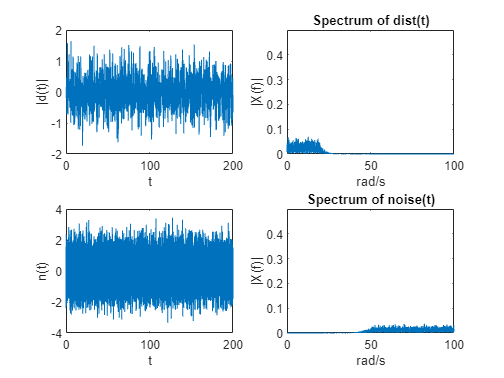

dt = 0.01; Fs = 1/dt;
F = 1/(s/5+1);
T = 0:dt:200;

% Create disturbance
D = 2*randn(length(T),1);
wc = (20/2/pi)/(Fs/2); % Normalized cutoff frequency (10 rqd/s)
[fb,fa] = butter(10,wc,'low'); % butter worth filter.
d = filter(fb,fa,D); % Now filter the disturbance. This generates colored noise
L = length(T)+1;

NFFT = 2^nextpow2(L); % Next power of 2 from length of y
Z = 2*fft(d,NFFT)/L;
f = Fs/2*linspace(0,1,NFFT/2+1); % Only interested in signals upto Fs/2 Hz.
absZ = abs(Z(1:NFFT/2+1));
figure(3);
subplot(2,2,1);plot(T,d);
xlabel('t'); ylabel('|d(t)|');

subplot(2,2,2);plot(2*pi*f,absZ); axis([0 100 0 .5]);
title('Spectrum of dist(t)');
xlabel('rad/s');
ylabel('|X(f)|');

% Create sensor noise
N = randn(length(T),1);
wc = (50/2/pi)/(Fs/2); % Normalized cutoff frequency (10 Hz)
[fb,fa] = butter(10,wc,'high'); % butter worth filter.
n = filter(fb,fa,N); % Now filter the disturbance. This generates colored noise
L = length(T)+1;

NFFT = 2^nextpow2(L); % Next power of 2 from length of y
Z = fft(n,NFFT)/L;
f = Fs/2*linspace(0,1,NFFT/2+1); % Only interested in signals upto Fs/2 Hz.
absZ = 2*abs(Z(1:NFFT/2+1));
figure(3);
subplot(2,2,3);plot(T,n);
xlabel('t');
ylabel('n(t)');

subplot(2,2,4);plot(2*pi*f,absZ); axis([0 100 0 .5]);
title('Spectrum of noise(t)');
xlabel('rad/s');
ylabel('|X(f)|');


% Save Data
P = G;
distTime = d;
noiseTime = n;

save heli.mat P distTime noiseTime T

## Controller Design

This is how I got the numbers.

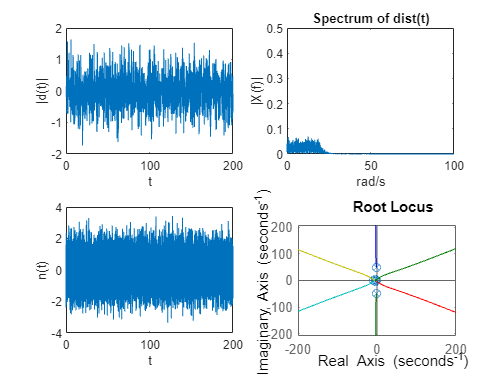

K = 100;
Ki = 30;
Kd = 200;

C = K + Ki/s + Kd*s/(s/10+1); % PID

Gyr = C*G/(1+C*G);
Gyd = G/(1+C*G);
Gyn = -Gyr;
Gur = C/(1+C*G);

rlocus(Gyr)

## Time Simulation

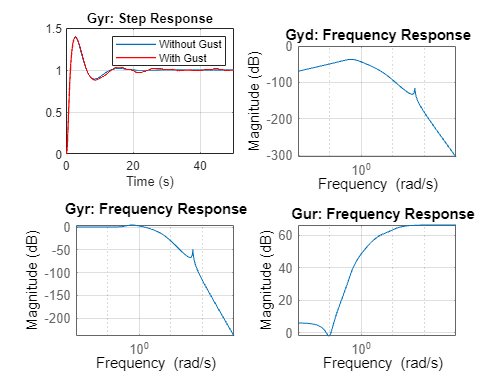

Y1 = step(Gyr,T);
Y2 = lsim(Gyd,10*d,T);
Y3 = lsim(Gyn,n,T);
u = step(Gur,T);

figure(2); clf;
subplot(2,2,1); plot(T,Y1,'Linewidth',1); title('Gyr: Step Response'); xlabel('Time (s)'); grid on;
hold on; plot(T,Y1+Y2,'r','Linewidth',1); xlim([0,50]); legend('Without Gust','With Gust');

subplot(2,2,2); bodemag(Gyd); title('Gyd: Frequency Response'); grid on;
subplot(2,2,3); bodemag(Gyr); title('Gyr: Frequency Response'); grid on;
subplot(2,2,4); bodemag(Gur); title('Gur: Frequency Response'); grid on;

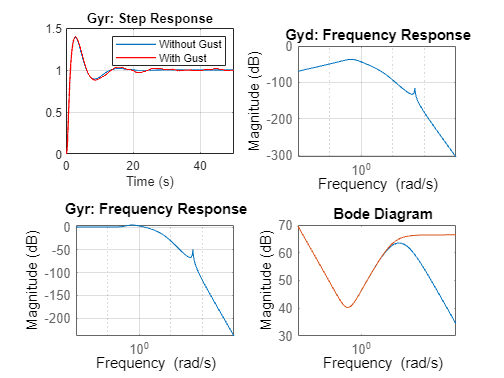

filterC = 1/(s/25+1);
newC = C*filterC;
figure(4);
bodemag(newC,C);

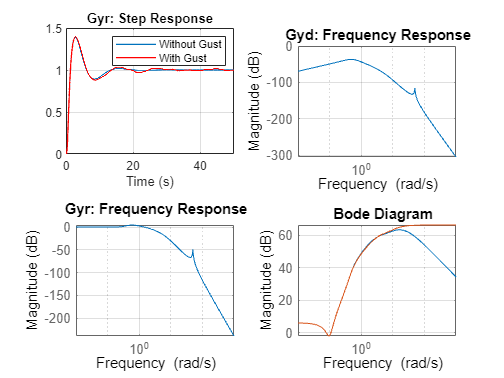

newGur = newC/(1+newC*G);
figure(2); subplot(2,2,4); hold on;
bodemag(newGur,Gur); grid on